#### Definición de los parámetros del sistema

Partiendo de los valores dados de separación entre portadoras e índices de las mismas. Debido al modo de funcionamiento de los índices de Matlab, es necesario sumar una unidad a los valores de índices $k$ dados.


$$\Delta f=200\textrm{Hz}$$
    
$$k=\left\lbrack 29,\ldotp \ldotp \ldotp ,38\right\rbrack$$
    
$$\textrm{kmax}=38$$


Se debe verificar, para una correcta modulación OFDM, que $\textrm{NFFT}>2\textrm{kmax}$. Por tanto el valor de $\textrm{NFFT}$ mínimo es ${\textrm{NFFT}}_{\textrm{MIN}} =76$. Sin embargo, este valor no cumple la premisa fundamental de la transformada rápida de Fourier, ya que este debe ser múltiplo de dos, es decir, se debe cumplir que $\textrm{NFFT}=2^k$ siendo $k$ un número natural distinto de cero. Como el valor calculado es el mínimo, se debe utilizar un valor de $k$ que resulte en un valor superior, por ejemplo $\textrm{NFFT}=2^7 =128$, el cuál es superior al mínimo valor calculado y es múltiplo de dos.

La frecuencia de muestreo se calcula a partir de la expresión $\textrm{Fs}=\textrm{NFFT}\cdot \Delta F=128\cdot 200=25600\;\textrm{Hz}$. El número de portadoras es el indicado por el enunciado de la práctica. $N_f =10$.

clear; close all, format compact

NFFT  =	128;            % Tamaño de la FFT. Para mayor velocidad debe ser múltiplo de dos
df    = 200;            % Separación entre portadoras
Fs    =	25600;          % Frecuencia de muestreo
Nf    =	10;             % Numero de portadoras con datos
m_ary =	4;              % Indicador de modulacion digital de cada portadora
SNR_vector = -10:2:10;  % Vector de relaciones SNR en el canal

Nofdm  = 100;                   % Número de símbolos OFDM
Nbits = Nofdm*Nf*log2(m_ary);   % Número de bits a transmitir
txbits = round(rand(1,Nbits));  % Generación bits aleatorios

#### Modulación QPSK

Se modulan los bits generados anteriormente mediante modulación QPSK.

% Modulación QPSK
xmod = moduladorQPSK(txbits);

#### Modulación OFDM

El vector con los símbolos modulados en QPSK posee una longitud de $\textrm{Nf}\cdot \textrm{Nofdm}$. Cada $\textrm{Nf}$ símbolos QPSK se modulan en un símbolo OFDM, por tanto el resultado de la modulación OFDM serán $\textrm{Nofdm}$ símbolos OFDM, cada uno de ellos con $\textrm{Nf}$ símbolos QPSK.

% Modulación OFDM
X = zeros(NFFT, Nofdm);

X(29:38,:) = reshape(xmod,Nf,Nofdm);
X = X + flipud(conj(X));
x = ifft(X, NFFT,'symmetric')*NFFT;
x = reshape(x,1,NFFT*Nofdm);

A continuación se muestra la representación temporal de la señal OFDM modulada.

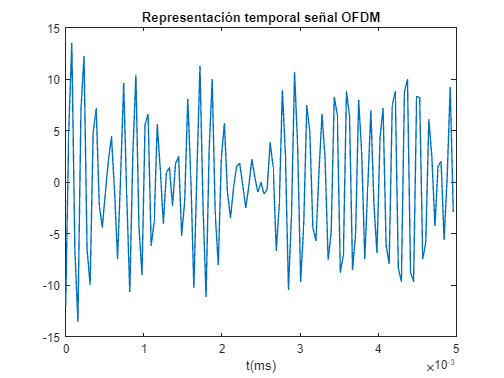

% Representación de gráficas temporales
T = 1/df;
Ts = 1/Fs;
t = 0:Ts:T-Ts;

figure;
plot(t,real(x(1:NFFT)));
xlabel('t(ms)');
title('Representación temporal señal OFDM')

#### Medidas de potencia

En esta sección se calculan y representan gráficamente la potencia de la señal, la potencia media, la potencia pico y PAPR.

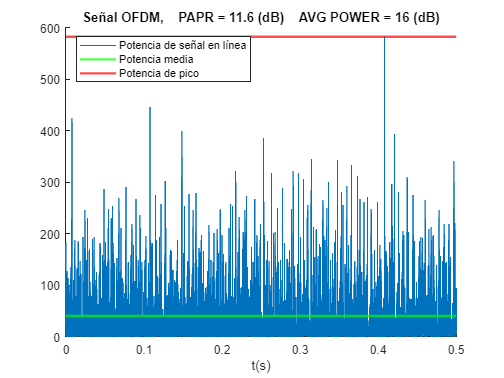

% Medidas de potencia
t = linspace(0,length(x)/Fs,length(x));
signal_pow = abs(x).^2;
avg_pow = mean(signal_pow);
peak_pow = max(signal_pow);
papr_dB = 10*log10(abs(peak_pow/avg_pow));

% Representación de las potencias calculadas
figure;
hold on;
plot(t,signal_pow);
yline(avg_pow,'LineWidth',2,'Color','g');
yline(peak_pow,'LineWidth',2,'Color','r');
xlabel('t(s)');  
legend('Potencia de señal en línea', 'Potencia media', 'Potencia de pico','location','best');  
title(['Señal OFDM,    PAPR = ' num2str(round(papr_dB,1)), ' (dB)','    AVG POWER = ', num2str(round(10*log10(avg_pow),1)), ' (dB)']);

#### Canal y representación de la probabilidad de error

El factor de ancho de banda indica cuanto del ancho de banda total está utilizando cada símbolo o canal OFDM. En la señal enviada solamente 20 de las 128 portadoras contienen información, sin embargo la longitud de la FFT utilizada es de 128. Cada canal o símbolo OFDM ocupa un $\frac{20}{128}\cdot 100\approx 16%$ del ancho de banda total. Esto implica que un $84%$ del espectro de la señal no está siendo utilizado para la transmisión de datos.

Este parámetro en dB indica la reducción de ruido lograda en cada subportadora. A menor número de símbolos o canales OFDM, mayor reducción de ruido. Este parámetro varia entre $-21\textrm{dB}<\textrm{fb}\left\lbrack \textrm{dB}\right\rbrack <0\textrm{dB}$ en el caso de una NFFT de 128. Para el caso presentado en el enunciado de la práctica de 20 subportadoras, la reducción en ruido es de aproximadamente $8\textrm{dB}$.

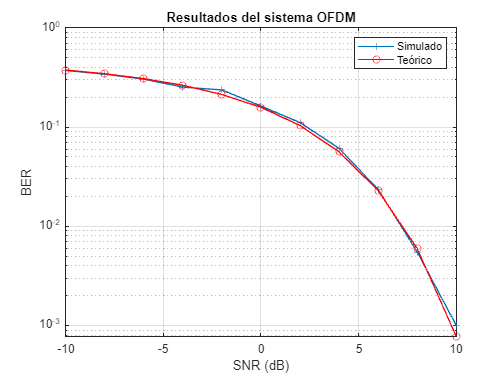

% Bucle de cálculo de las probabilidades de error
for snrIter = 1:length(SNR_vector)
    fb = 10*log10( (NFFT/2)/Nf );
    y  = awgn(x,SNR_vector(snrIter)-fb,'measured');
    y = reshape(y,NFFT,Nofdm);
    
    Y = fft(y,NFFT)/NFFT; 
    ydemod = Y(29:38,:);
    ydemod = (reshape(ydemod,1,Nf*Nofdm)).';
    
    rxbits = demoduladorQPSK(ydemod);
    BER(snrIter) = sum(xor(rxbits,txbits))/length(rxbits);
end

% Cálculo probabilidad de error teórica
gamma  = 10.^((SNR_vector-3)/10);  
BERTeo = qfunc(sqrt(2*gamma));
BERTeo(find(BERTeo<1e-5)) = NaN;  

% Representación BER
figure;
semilogy(SNR_vector, BER,'-+');
hold on;
semilogy(SNR_vector, BERTeo, '-rO');
legend('Simulado','Teórico')
xlabel('SNR (dB)');  ylabel('BER')
grid on;
title('Resultados del sistema OFDM')

#### Representación espectral de la señal

En este último apartado se muestra el espectro de las frecuencias positivas con un SNR de $15\textrm{dB}$. Se puede observar como en la banda de interés (desde la primera subportadora $K=29$ hasta la última $K=38$) el valor de la señal es más elevado y carece de aleatoriedad, denotando que no se trata de solamente ruido blanco a diferencia de en el resto de la señal. Esto demuestra que el espectro de la señal trasmitido está donde inicialmente se había previsto.

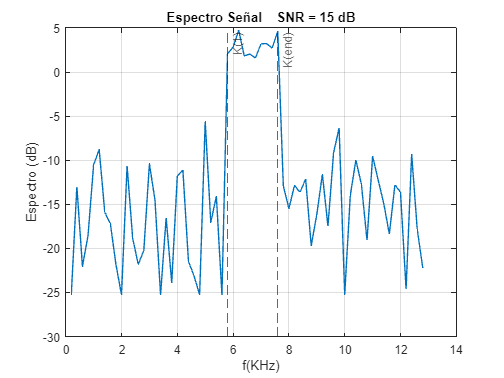

K = 29:38;
SNR = 15;
fb = 10*log10( (NFFT/2)/Nf );
y  = awgn(x,SNR-fb,'measured');
y = reshape(y,NFFT,Nofdm);

Y = fft(y,NFFT)/NFFT;
frec = df:df:NFFT/2*df;

XdB(1:NFFT/2) = 20*log10(abs(Y(1:NFFT/2)));
XdB(find(XdB<max(XdB)-30)) = max(XdB)-30;

% Representación espectral
figure;
plot(frec*1e-3, XdB);
xline([K(1)*df/1000 K(end)*df/1000],'--',{'K(1)','K(end)'});
grid on;
xlabel('f(KHz)');   
ylabel('Espectro (dB)');
title(['Espectro Señal','    SNR = ',num2str(SNR),' dB'])

## FUNCIONES UTILIZADAS EN LA PRÁCTICA

function xMod = moduladorQPSK(txBits)
%%
%  Esta función genera una señal modulada en QPSK en función de un vector de parejas de bits
%
% txBits    vector fila de bits de entrada. Su longitud debe ser par
% xMod      vector fila de símbolos modulados en QPSK en banda base. 
%           Sus elementos son números complejos y su longitud la mitad de la de txbits
%
% Comprobación de que la longitud de txBits es par
  n = length(txBits);
  if rem(n,2)~ 0;
      error('La longitud de txBits no es par');
  end
%
% Copia de txBits a vector fila
  b = txBits(:)';
%
% Se generan los vectores I (fase) y Q (cuadratura)
% Los 1s se asimilan a fase 0 (+1) y los 0s a fase pi (-1)
  b = (reshape(b', 2, n/2) - 0.5)*2;
  I = b(1,:);
  Q = b(2,:);
%
% Se genera la señal modulada como suma de señales BPSK en fase y cuadratura
  xMod = I + j*Q;
 %
end

function rxBits = demoduladorQPSK(rxSimbol)
%%
%  Esta función demodula una señal QPSK en banda base, contenida en el vector de entrada rxSimbol
%
% rxSimbol  vector fila de símbolos de entrada. 
% xmod      vector fila de bits resultado de demodular. Su longitud el doble de la de rxSimbol
%
% Inicialización
  n = length(rxSimbol);
  rxBits = zeros(1, 2*n);
%
% Copia de rxSimbol a vector fila
  b = rxSimbol(:).';
%
% Se generan los vectores I (fase) y Q (cuadratura) 
%
  I   = zeros(1,n);
  ind = find(real(b)>=0);
  I(ind) = 1;
  Q   = zeros(1,n);
  ind = find(imag(b)>=0); 
  Q(ind) = 1;
%
% Se genera el vector de bits en base a I y Q
  rxBits = reshape([I ; Q], 1, 2*n); 
%
end
